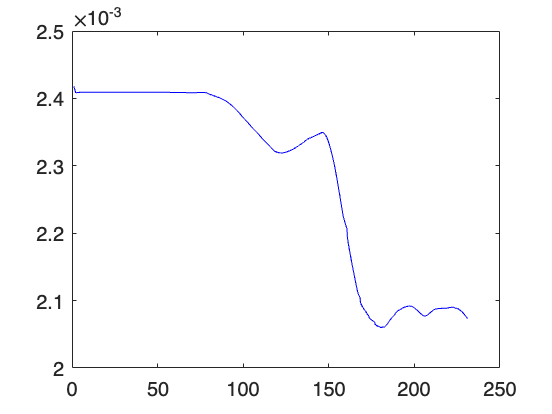

% Load the sensor data from the .csv file.
data = readmatrix("./data-collection/Sample_Log_2022_05_09.csv");

[row, col]= size(data);

time = data(:,1);

% weight
% (1)
empty_airplane_lbs = 91300;
cargo_lbs = 0;
fuel_1_lbs = data(:,188);
fuel_2_lbs = data(:,189);
fuel_3_lbs = data(:,190);

total_lbs = fuel_1_lbs + fuel_2_lbs + fuel_3_lbs + empty_airplane_lbs + cargo_lbs;

% forward speed
% (2)
u_speed_fps = data(:,43);

% airspeed
% (3)
airspeed_kts = data(:,32);
airspeed_fps = airspeed_kts * 1.6878099;

% air density
% (4)
air_pressure_inhg = data(:,248);
air_pressure_psi = air_pressure_inhg * 0.491154;

% https://www.engineeringtoolbox.com/individual-universal-gas-constant-d_588.html
R_ftlb_per_slug_R__air = 1717;
R_J_per_slug_R__air = R_ftlb_per_slug_R__air * 1.355818;
R_Pa_m_cubed_per_slug_R__air = R_J_per_slug_R__air;
R_psi_m_cubed_per_slug_R__air = R_Pa_m_cubed_per_slug_R__air * 0.000145038;
R_psi_ft_cubed_per_slug_R__air = R_psi_m_cubed_per_slug_R__air * 35.314666572222;

% TODO: can get this.. not working
temperature_F = 50;
temperature_R = temperature_F + 459.67;

rho = air_pressure_psi / R_psi_ft_cubed_per_slug_R__air / temperature_R;

% acceleration
% (5)
% TODO: can get this.. not working
a_v = 0;

% thrust
% (6) - not sure
T = 0;

% drag
% (7) - not sure
D = 0;

% climb angle
% (8)
% TODO: can get this.. not working
c = 0;

% center of gravity
% (9) - pretty sure
x_cg = 0;
% (10) - pretty sure
x_ac = 0;
% (11) - pretty sure
l_t = 0;

figure
plot(time, rho, 'b-');


% figure
% yyaxis left;
% plot(time,indicated_alt_ft_alt,'g-',time,indicated_alt_ft_gps,'b-',time,alt_agl_ft_pos,'m-',time,alt_ft_pos,'r-');
% 
% yyaxis right;
% plot(time,elevator,'black-')
% 
% legend(["indicated alt ft alt" "indicated al ft gps" "alt agl ft pos" "alt ft pos" "elevator"]);